clear
close all

Vb = 2.5;
Vout = 10;
L = 10e-6;
fs = 100e3;
Ib = Vb/fs/L;
Jm = 4/Ib;

N = 500;
K = 2000;
M = 200

M = 200

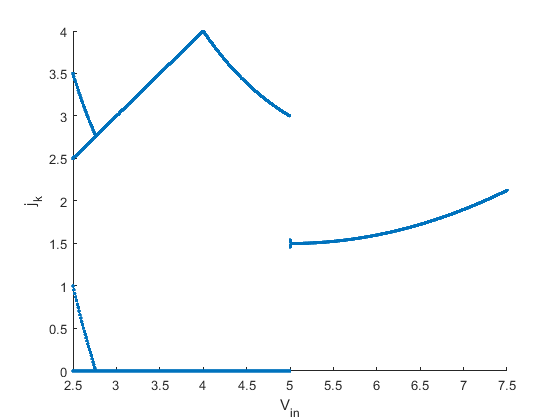

Vin = linspace(2.5,7.5,N);
jo = zeros(1,K);
figure;
hold all
for n = 1:N
    j = zeros(1,K);
    m1 = Vin(n)/Vb;
    m2 = (Vin(n)-Vout)/Vb;
    for k=2:K
        j(k) = stepj(j(k-1),m1,m2,Jm);
    end
    plot(Vin(n).*ones(1,M),j(K-M+1:K)*Ib,'.','Color',[0 0.4470 0.7410], 'LineWidth', 0.1)
end
ylabel('j_k')
xlabel('V_{in}')

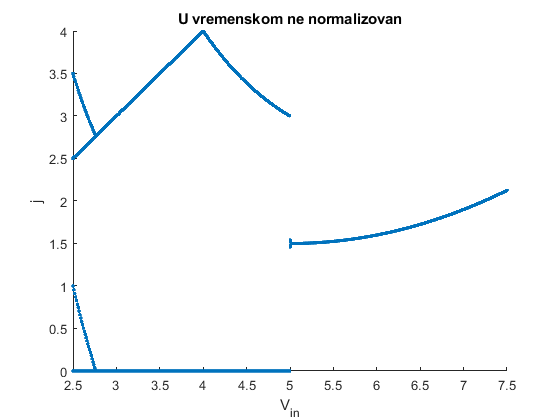

jo = zeros(1,K);
figure;
hold all
for n = 1:N
    j = zeros(1,K);
    m1 = Vin(n)/L/fs;
    m2 = (Vin(n)-Vout)/L/fs;
    for k=2:K
        j(k) = stepj(j(k-1),m1,m2,4);
        
    end
    plot(Vin(n).*ones(1,M),j(K-M+1:K),'.','Color',[0 0.4470 0.7410], 'LineWidth', 0.1)
end
ylabel('j_k')
xlabel('V_i_n')
title('U vremenskom ne normalizovan')

function J1 = stepj(J0,m1,m2,Jm)
    d = (Jm-J0)/m1;
    if (d>1)
        J1 = J0 + m1;
        return
    end
    J1 = Jm + (1 - d) * m2;
    if (J1 < 0)
        J1 = 0; 
    end
end
